save_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\';

load('E:\work_Code\Matlab\Toolbox\brain_science\Registration\SphericalDemons_SDv1.5.1\zys_DIY\SphericalDemons\freesurfer\lh.DW.Atlas1to39.2.10.mat')
SD_atlas_raw = SD_atlas;
SD_atlas_new = SD_atlas;

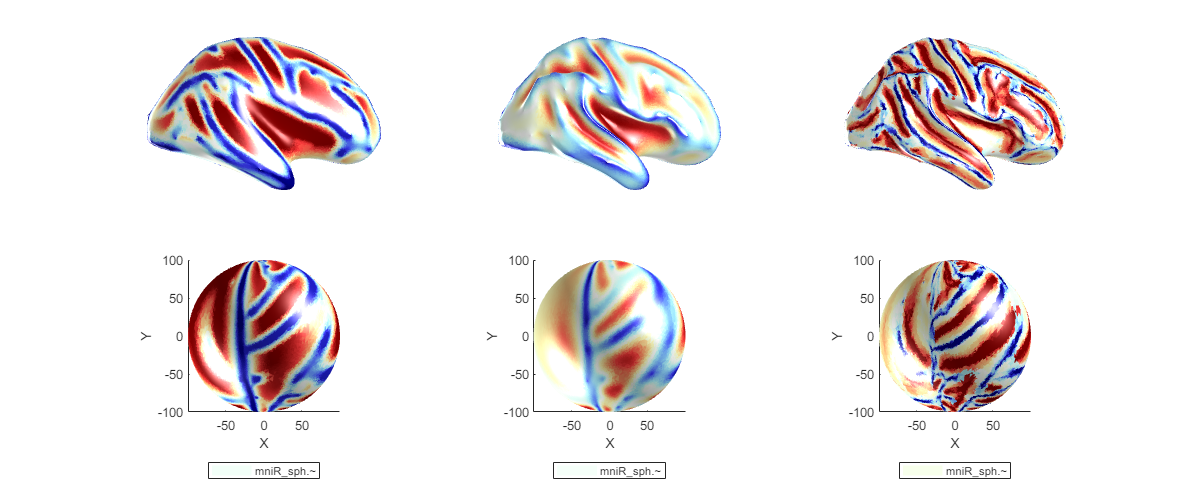

surf_raw = mniR_pialR_bin2;
sm_iters = [50,100,400];

surf_mniR = surf_raw;
[mniR_sph] = Surf_func_ROI(surf_raw,'mapping_sphere','fine',0,'get_field',0,'keep_area',0);
surf_sm1 = Surf_smooth(surf_raw,'iter',sm_iters(1),'type',3);

mniR_curv1 = Surf_func_Val(surf_sm1,'curvature','fine',0);
mniRK1 = mat_cut(mniR_curv1.k1,'10','90');
mniRK1re = mniRK1;
mniRK1re(mniRK1re<0) = 4*mniRK1re(mniRK1re<0);

[surf_sm2] = Surf_smooth(surf_sm1,'iter',sm_iters(2),'type',3);
% mniR_curv2 = Surf_func_Val(surf_sm2,'curvature','fine',0);
mniRK2 = get_reduce_curvK1(surf_sm2,16,mniR_sph.Vertices);
mniRK2 = mat_cut(mniRK2,'10','90');

[surf_sm3] = Surf_smooth(surf_sm2,'iter',sm_iters(3),'type',3);
mniR_sm3 = surf_sm3;
mniRK3 = get_reduce_curvK1(surf_sm3,32,mniR_sph.Vertices);
mniRK3 = mat_cut(mniRK3,'10','90');

val = [mniRK3,mniRK2,mniRK1re];
val = surf_valsmooth(surf_raw,val,50);
mniRK3 = val(:,1); mniRK2 = val(:,2); mniRK1sm = val(:,3);
mniRK1sm = mat_cut(mniRK1sm,'10','90');

temp = min((mniRK1sm-mean(mniRK1sm))./std(mniRK1sm),(mniRK3-mean(mniRK3))./std(mniRK3));
mniRK3 = mat_cut(temp,'10','90');

[mniR_sph] = Surf_func_ROI(surf_sm3,'mapping_sphere','fine',0,'get_field',0,'keep_area',0);
mniR_sph.Vertices = mniR_sph.Vertices/mniR_sph.radius*SD_atlas.radius;
mniR_sph.radius = SD_atlas.radius;

figure;
next; colormapa(cmap_sign); plot_surf(surf_sm3,'colors',mniRK3);
next; colormapa(cmap_sign); plot_surf(surf_sm2,'colors',mniRK2);
next; colormapa(cmap_sign); plot_surf(surf_sm2,'colors',mniRK1); % caxis([-1,1]/2);
lay_fig([12,5]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(90,0)
next; colormapa(cmap_sign); plot_surf(mniR_sph,'colors',mniRK3);
next; colormapa(cmap_sign); plot_surf(mniR_sph,'colors',mniRK2);
next; colormapa(cmap_sign); plot_surf(mniR_sph,'colors',mniRK1); % caxis([-1,1]/2);

% surf_in = surf_raw; num_modes = 8;
% mniR_eigenmodes = get_surfEigmode(surf_in,num_modes);
% fig = draw_surface_bluewhitered_gallery_dull(Surf_lower(surf_in), mniR_eigenmodes, hemisphere, [], 0); lay_linkview

figure;
for atlas_level = 1:3
    sMesh = SD_atlas_raw.basic_atlas{atlas_level};
    points = sMesh.vertices;

    switch atlas_level
        case 1
            val_raw = mniRK3;
            % temp = abs(mniRK3)>abs(mniRK2); val_raw = temp.*mniRK3 + (1-temp).*mniRK2;
        case 2
            val_raw = mniRK3;
        case 3
            val_raw = mniRK1;
            % temp = abs(mniRK2)>abs(mniRK1); val_raw = temp.*mniRK2 + (1-temp).*mniRK1;
    end
    % val_raw = mat_cut(val_raw,-0.5,0.5);

    tic
    v = mniR_sph.Vertices;
    v_q = double(points');

    val_new = interp_sph(v,val_raw,v_q);
    toc

    v = single(sMesh.vertices);
    v = v./vecnorm(v,2,2)*SD_atlas.radius;

    if i == 3
        val_new(val_new<-3) = -3; val_new(val_new>3) = 3;
    end

    mesh_new = struct('Vertices', v', 'Faces', sMesh.faces');
    next; colormapa(jet); plot_surf(mniR_sph,'colors',val_raw); legend off; axis off
    next; colormapa(jet); plot_surf(mesh_new,'colors',val_new); legend off; axis off

    SD_atlas_new.basic_atlas{atlas_level}.mean = val_new';

    temp = 0.25*sqrt(abs(val_new - mean(val_new))) + mean(val_new);
    SD_atlas_new.basic_atlas{atlas_level}.variance = temp';
end

历时 0.199210 秒。
历时 0.203367 秒。
历时 0.265258 秒。


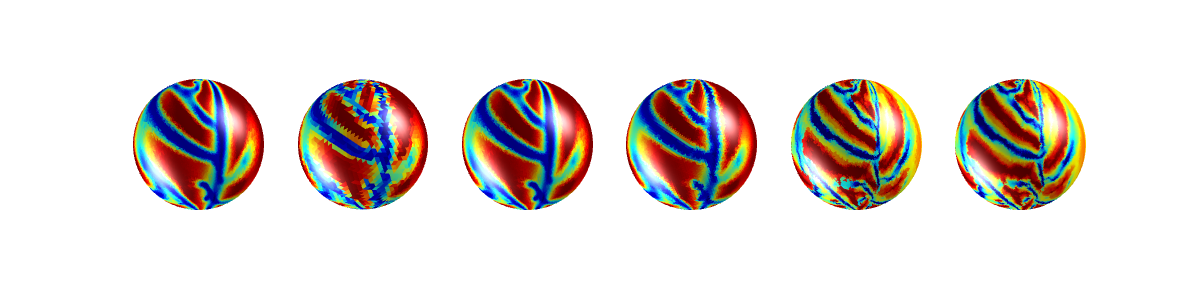

lay_fig([12,3]); lay_linkview(gcf,'view'); view(0,90)

SD_atlas = SD_atlas_new;

SD_atlas.basic_atlas(4:end) = [];
SD_atlas.parms.data_filename_cell = {'inflated.H','sulc','curv'};
SD_atlas.parms.uniform_meshes(4:end) = [];

SD_atlas.yrotate = 0; SD_atlas.zrotate = 0;

save('E:\work_Code\Matlab\Toolbox\brain_science\Registration\SphericalDemons_SDv1.5.1\zys_DIY\SphericalDemons\freesurfer\lh.DW.zys.mat','SD_atlas')

% mris_SD_register('../../test_data_zys/sub-00002/surf/lh.sphere', 'lh.DW.zys.mat', '../../test_data_zys/sub-00002/surf/lh.sphere.SD.reg');

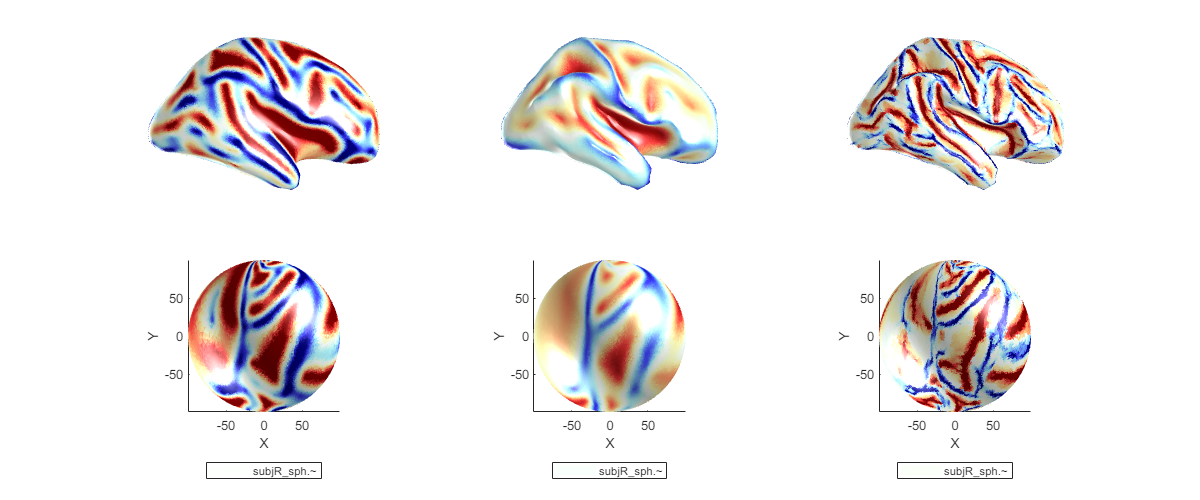

subjR_file = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00004\surf\T1_reg.DL.left.inner.ply';
surf_raw = Surf_read_Data(subjR_file);
surf_subjR = surf_raw;

[subjR_sph] = Surf_func_ROI(surf_raw,'mapping_sphere','fine',0,'get_field',0,'keep_area',0);
% subjR_sph.Vertices = 1*mniR_sph.Vertices+0*subjR_sph.Vertices;
surf_sm1 = Surf_smooth(surf_raw,'iter',sm_iters(1),'type',3);

subjR_curv1 = Surf_func_Val(surf_sm1,'curvature','fine',0);
subjRK1 = mat_cut(subjR_curv1.k1,'10','90');
subjRK1re = subjRK1;
subjRK1re(subjRK1re<0) = 4*subjRK1re(subjRK1re<0);

[surf_sm2] = Surf_smooth(surf_sm1,'iter',sm_iters(2),'type',3,'calc_dist',0);
subjRK2 = get_reduce_curvK1(surf_sm2,16,subjR_sph.Vertices);
subjRK2 = mat_cut(subjRK2,'10','90');

[surf_sm3] = Surf_smooth(surf_sm2,'iter',sm_iters(3),'type',3,'calc_dist',0);
subjR_sm3 = surf_sm3;
subjRK3 = get_reduce_curvK1(surf_sm3,32,subjR_sph.Vertices);
subjRK3 = mat_cut(subjRK3,'10','90');

val = [subjRK3,subjRK2,subjRK1re];
val = surf_valsmooth(surf_raw,val,50);
subjRK3 = val(:,1); subjRK2 = val(:,2); subjRK1sm = val(:,3);
subjRK1sm = mat_cut(subjRK1sm,'10','90');

% temp = min((subjRK1sm-mean(subjRK1sm))./std(subjRK1sm),(subjRK3-mean(subjRK3))./std(subjRK3));
subjRK3 = mat_cut(subjRK1sm,'10','90');

[subjR_sph] = Surf_func_ROI(surf_sm3,'mapping_sphere','fine',0,'get_field',0,'keep_area',0);
% subjR_sph = subjR_sphreg;
subjR_sph = Surf_smooth(subjR_sph,'iter',3,'type',3);
subjR_sph.Vertices = subjR_sph.Vertices./vecnorm(subjR_sph.Vertices,2,2)*SD_atlas.radius;

figure;
next; colormapa(cmap_sign); plot_surf(surf_sm3,'colors',subjRK3);
next; colormapa(cmap_sign); plot_surf(surf_sm2,'colors',subjRK2);
next; colormapa(cmap_sign); plot_surf(surf_sm2,'colors',subjRK1); % caxis([-1,1]/2);
lay_fig([12,5]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(90,0)
next; colormapa(cmap_sign); plot_surf(subjR_sph,'colors',subjRK3);
next; colormapa(cmap_sign); plot_surf(subjR_sph,'colors',subjRK2);
next; colormapa(cmap_sign); plot_surf(subjR_sph,'colors',subjRK1); % caxis([-1,1]/2);

% addpath(genpath('E:\work_Code\Matlab\from_github\BrainEigenmodes-main\'))
% num_modes = 8; hemisphere = 'lh';
% surf_in = surf_raw;
% % figure
% % h = plot_surf(surf_in); view(-90,0)
% % rotate(h,[1,0,0],-30); rotate(h,[0,1,0],-40)
% % surf_in = Surf_read_Data(h);
% subjR_eigenmodes = get_surfEigmode(surf_in,num_modes);
% fig = draw_surface_bluewhitered_gallery_dull(Surf_lower(surf_in), subjR_eigenmodes, hemisphere, [], 0); lay_linkview

freesurf_matdir = 'E:\work_Code\Python\Packages\freesurfer-Linux-v6.0.0\matlab';

addpath(freesurf_matdir)
save_dir = 'E:\work_Code\Matlab\Toolbox\brain_science\Registration\SphericalDemons_SDv1.5.1\zys_DIY\test_data_zys\sub-00002\surf\';

v = subjR_sph.Vertices;
v = v./vecnorm(v,2,2)*SD_atlas.radius;

write_surf([save_dir,'lh.sphere'],v,subjR_sph.Faces);

...subtracting 1 from face indices for FreeSurfer compatibility.



val_save = subjRK3;
write_curv([save_dir,'lh.inflated.H'], val_save, size(subjR_sph.Faces,1));
val_save = subjRK3;
write_curv([save_dir,'lh.sulc'], val_save, size(subjR_sph.Faces,1));
val_save = subjRK1;
write_curv([save_dir,'lh.curv'], val_save, size(subjR_sph.Faces,1));

rmpath(freesurf_matdir)
% mris_SD_register('../../test_data_zys/sub-00002/surf/lh.sphere', 'lh.DW.zys.mat', '../../test_data_zys/sub-00002/surf/lh.sphere.SD.reg');

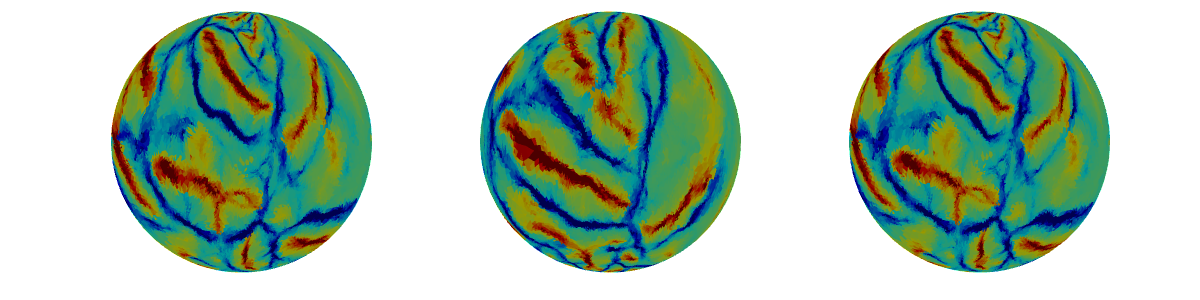

reg_sph = mniR_sph; reg_sph.Vertices = read_surf([save_dir,'lh.sphere.SD.reg']);

figure; lay_sub(1,3)
next; colormapa(jet); plot_surf(subjR_sph,'colors',subjRK1);
next; colormapa(jet); plot_surf(mniR_sph,'colors',mniRK1);
next; colormapa(jet); plot_surf(reg_sph,'colors',subjRK1);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(0,90); lay_fig('func','clim([-1,1]/2)');

im_fix_cat = amp(img_mniR);
im_mov_cat = amp(img_subjR);

bound_sz = size(im_mov_cat);
pts_sz = [5,4];
x = linspace(1,bound_sz(2),pts_sz(2)); y = linspace(1,bound_sz(1),pts_sz(1));
movingPts = [x,y*0+bound_sz(2),fliplr(x),y*0; x*0,y,x*0+bound_sz(1),fliplr(y)];
fixedPts = movingPts;
reg_params = struct('Metric0Weight',1,'Metric1Weight',0.2,'NumberOfResolutions',3,'NumberOfSpatialSamples',2000);
params = {};
% params = {'movingPts',movingPts,'fixedPts',fixedPts,'reg_params',reg_params};

t_tic = tic;
[sReg,trans_params,def_field] = MRI_register(im2uint8(im_fix_cat),im2uint8(im_mov_cat),'reg_type','nonrigid', ...
    'auto_params',20,'get_field',1,'field_type','xyz',params{:});

Saved successfully in : 0.043 s.
Saved successfully in : 0.052 s.
    FinalGridSpacingInPhysicalUnits: [20 20 20]
                   SampleRegionSize: [20 20 20]
                  ResultImageFormat: 'tif'

    1: E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid2D-OpenCL.txt    

    {'E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\elastix\elastix'                        }
    {'f "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\fix.tif"'                     }
    {'m "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\mov.tif"'                     }
    {'out E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\RegResult'                           }
    {'p "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid2D-OpenCL.txt"'}

 
elastix is started at Sun Jan 21 01:28:29 2024. 
 
which elastix:   E:\work_Code\Matlab\ZYS\DIY_App\Elastix_too

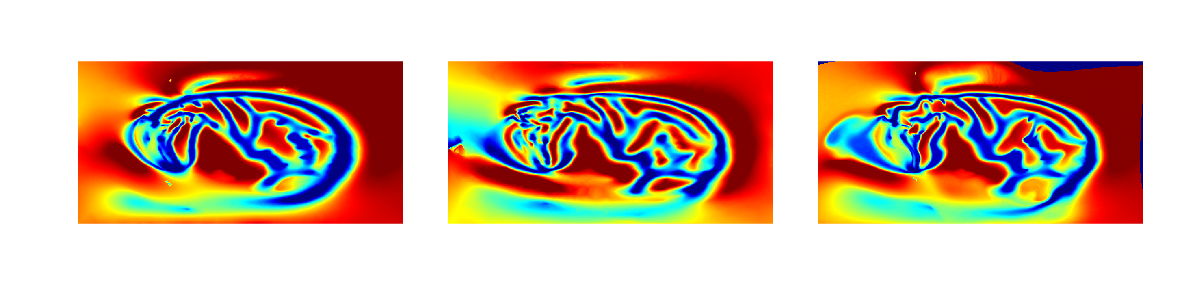


figure; lay_sub(1,3); colormap jet
next; showc(im_fix_cat);
next; showc(im_mov_cat);
next; showc(sReg.data);
lay_fig([12,3]); lay_fig('func','legend off; axis off');

disp_toc(t_tic)

  |->  using 13.8s [==============================================] 2024-01-21 01:28:43


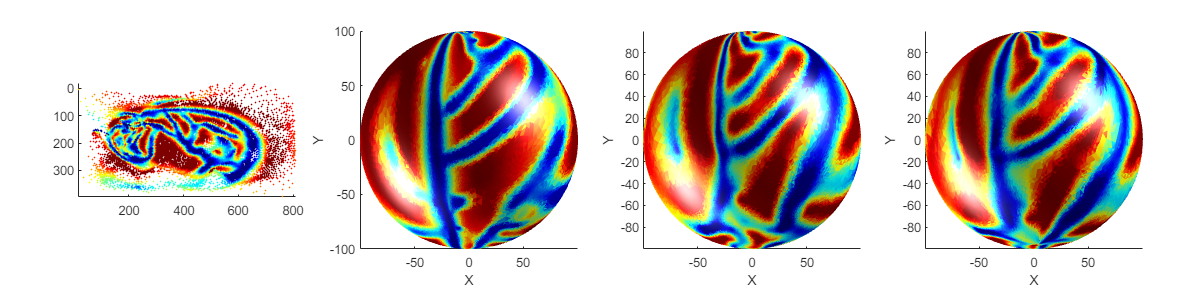

fix_bnd_sz = 20;
def_sz = size(def_field.data);
def_weight = ones(round(def_sz([1,2])/4));
def_weight = imfilter(def_weight,fspecial('average',fix_bnd_sz));
def_weight = imresize(def_weight,def_sz([1,2]));
def_weight = amp(def_weight,0).^2;

Vm = pts_warp(map_subjR*texNy,def_field,'field');
Vwarp = [];
Vwarp(:,1) = interp2(imgX_mniR,Vm(:,1),Vm(:,2));
Vwarp(:,2) = interp2(imgY_mniR,Vm(:,1),Vm(:,2));
Vwarp(:,3) = interp2(imgZ_mniR,Vm(:,1),Vm(:,2));

Vraw = sph_subjRdiv.Vertices;
weight = interp2(def_weight,Vm(:,1),Vm(:,2));
weight(isnan(weight)) = 0;
Vwarp(isnan(Vwarp)) = 0;
Vwarp = Vwarp.*weight + Vraw.*(1-weight);
Vwarp = Vwarp./vecnorm(Vwarp,2,2)*SD_atlas.radius;

surf_warp = subjR_sphreg; surf_warp.Vertices(vsubjR_idxR,:) = Vwarp;
[surf_warp] = Surf_smooth(surf_warp,'iter',30,'type',3);
surf_warp.Vertices = surf_warp.Vertices./vecnorm(surf_warp.Vertices,2,2)*SD_atlas.radius;

figure; lay_sub(1,4); colormap jet
next; plot_scatter(Vm,1,subjRK3_div); colormap jet; axis ij; axis tight
next; plot_surf(mniR_sph,'colors',mniRK3);
next; plot_surf(subjR_sphreg,'colors',subjRK3);
next; plot_surf(surf_warp,'colors',subjRK3);
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view');

failed trials

texN = 400;
[Xo,Yo,Zo,tex_demo] = Sph_map_base('mode','8c','pos',texN,'if_plot',0,'lim',1);
sph_8c = Surf_read_Data(surf2patch(Xo,Yo,Zo,'triangles'));
% sph_8c = Surf_func_ROI(sph_8c,'close8c');
% sph_8c = Surf_smooth(sph_8c,'iter',200,'type',3);
% sph_8c.Vertices = sph_8c.Vertices./vecnorm(sph_8c.Vertices,2,2);

figure;
next; plot_surf(sph_8c,'show_vl',1)

sph_8c.radius = SD_atlas.radius;
sph_8c.Vertices = sph_8c.radius*sph_8c.Vertices;

sph_types = {'mniR','subjR'};
for i = 1:2
    sph_type = sph_types{i};
    switch sph_type
        case 'mniR'
            sph_raw = mniR_sph;
            val_raw = mniRK3;
        case 'subjR'
            sph_raw = subjR_sph;
            val_raw = subjRK3;
    end

    f_interp_sph = @(val) interp_sph(sph_raw.Vertices,val,sph_8c.Vertices);
    val_8c = f_interp_sph(val_raw);

    img_8c = reshape(val_8c,texN,[]);
    % img_8c = imgaussfilt(img_8c,4);

    f_cat = @(img) [rot90(img,2),img; img,rot90(img,2)];
    f_crop = @(img) img(texN/2+1:end,1:texN*1.5);
    img_cat = f_crop(f_cat(img_8c));

    switch sph_type
        case 'mniR'
            im_fix = img_8c;
            im_fix_cat = img_cat;
        case 'subjR'
            im_mov = img_8c;
            im_mov_cat = img_cat;
    end

    figure; colormap jet
    next; plot_surf(sph_raw,'colors',amp(val_raw));
    next; plot_surf(sph_8c,'colors',amp(val_8c));
    lay_linkview(gcf,'view'); % view(-90,0)
    next; showc(amp(img_8c)); axis xy;
    next; showc(img_cat); axis xy;
    lay_fig([12,3]); lay_fig('func','legend off; axis off');
end

if_plot = 1;
val = subjR_eigenmodes(:,6); val_raw = val;
val = 1./(1+abs(val)/max(val)).*sign(val);
subjR_eigmode_re = val;

figure;
next; colormapa(cmap_sign); plot_surf(subjR_sph,'colors',subjRK3);
next; colormapa(cmap_sign); plot_surf(subjR_sph,'colors',val_raw);
next; colormapa(cmap_sign); plot_surf(subjR_sph,'colors',val);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(0,90)

[im_mov_cat,vdisk_mov] = sph2disk(subjR_sph,subjR_eigmode_re,texN,if_plot);

if_plot = 1;
val = mniR_eigenmodes(:,6); val_raw = val;
val = 1./(1+abs(val)/max(val)).*sign(val);
mniR_eigmode_re = val;

figure;
next; colormapa(cmap_sign); plot_surf(mniR_sph,'colors',mniRK3);
next; colormapa(cmap_sign); plot_surf(mniR_sph,'colors',val_raw);
next; colormapa(cmap_sign); plot_surf(mniR_sph,'colors',val);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(0,90)

[im_fix_cat, vdisk_fix] = sph2disk(mniR_sph,mniR_eigmode_re,texN,if_plot);

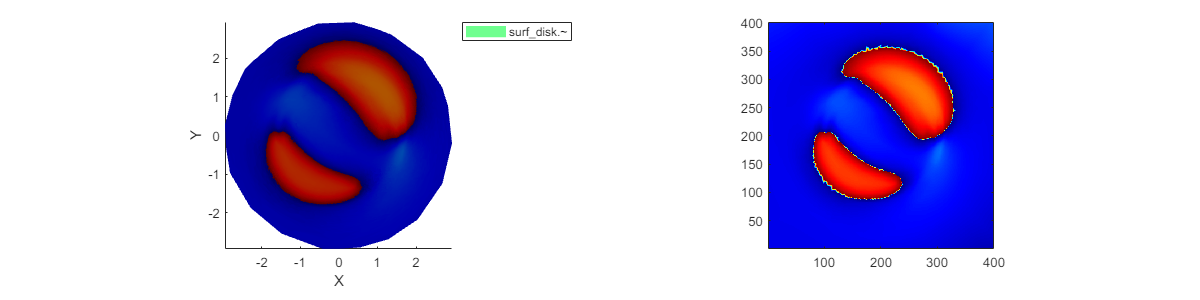

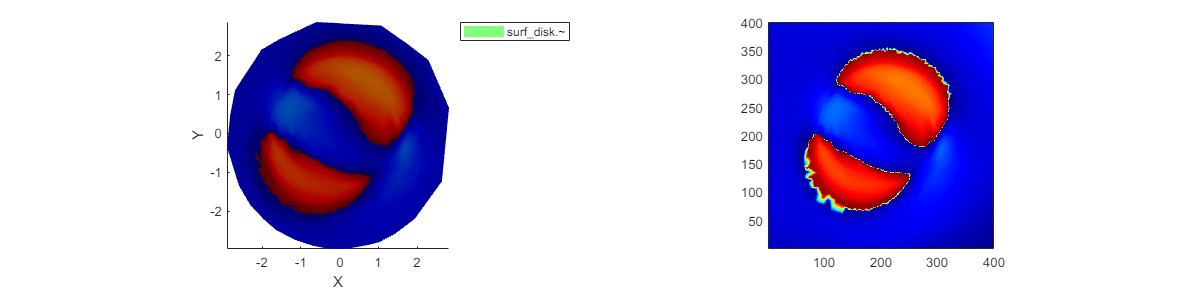

Saved successfully in : 0.073 s.
Saved successfully in : 0.041 s.
    FinalGridSpacingInPhysicalUnits: [18 18 18]
                   SampleRegionSize: [18 18 18]
                  ResultImageFormat: 'tif'

    1: E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid2D-OpenCL.txt    

    {'E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\elastix\elastix'                        }
    {'f "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\fix.tif"'                     }
    {'m "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\mov.tif"'                     }
    {'out E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\RegResult'                           }
    {'p "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid2D-OpenCL.txt"'}

 
elastix is started at Wed Jan 17 22:19:59 2024. 
 
which elastix:   E:\work_Code\Matlab\ZYS\DIY_App\Elastix_too

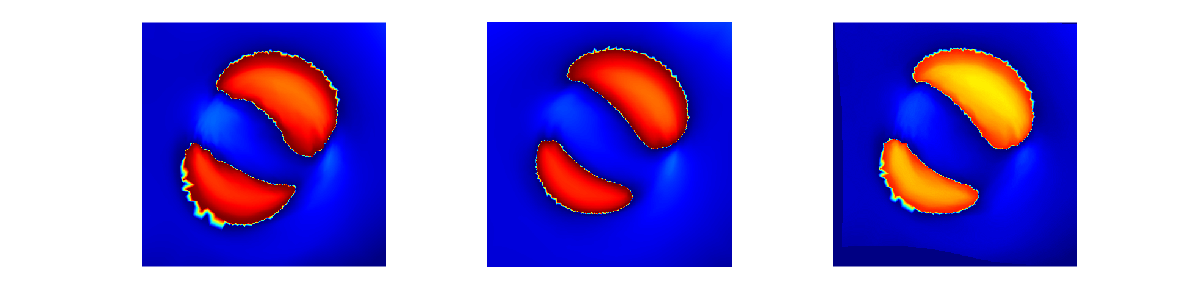

vdisk_mov_pts = (1+vdisk_mov/pi)*texN/2;
vdisk_warp_pts = pts_warp(vdisk_mov_pts,def_field,'field');
vdisk_warp = (2*vdisk_warp_pts/texN-1)*pi;
[TH,PHI] = cart2pol(vdisk_warp(:,1),vdisk_warp(:,2));
[X,Y,Z] = sph2cart(TH,PHI-pi/2,TH*0+SD_atlas.radius);
Vwarp = [Z,Y,X];

sph_warp = subjR_sph; sph_warp.Vertices = Vwarp;

figure; lay_sub(1,4); colormap jet
next; plot_surf(subjR_sph,'colors',8*subjRK3 + subjR_eigmode_re);
next; plot_surf(mniR_sph,'colors',8*mniRK3 + mniR_eigmode_re);
next; plot_surf(sph_warp,'colors',8*subjRK3 + subjR_eigmode_re);
lay_fig([12,3]); lay_fig('func','legend off;'); lay_linkview(gcf,'view'); % view(-90,0)

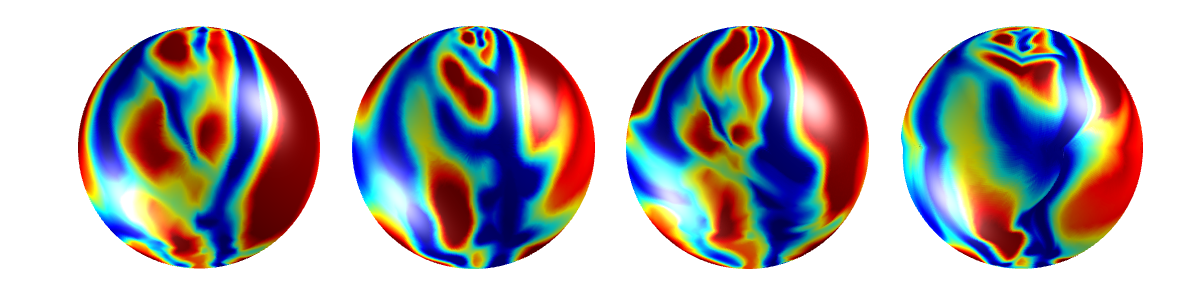

Xo_cat = f_crop(f_cat(Xo));
Yo_cat = f_crop(f_cat(Yo));
Zo_cat = f_crop(f_cat(Zo));

def_field.data = squeeze(def_field.data);

Xo_warp = MRI_warp(def_field,Xo_cat,'BST');
Xo_warp = Xo_warp.data(end-texN+1:end,1:texN);
Yo_warp = MRI_warp(def_field,Yo_cat,'BST');
Yo_warp = Yo_warp.data(end-texN+1:end,1:texN);
Zo_warp = MRI_warp(def_field,Zo_cat,'BST');
Zo_warp = Zo_warp.data(end-texN+1:end,1:texN);

sph_warp = Surf_read_Data(surf2patch(Xo_warp,Yo_warp,Zo_warp,'triangles'));
val_warp = sReg.data(end-texN+1:end,1:texN);

figure; lay_sub(1,4); colormap jet
next; plot_surf(sph_8c,'colors',amp(im_mov(:)));
next; plot_surf(sph_8c,'colors',amp(im_fix(:)));
next; plot_surf(sph_8c,'colors',amp(val_warp(:)));
next; plot_surf(sph_warp,'colors',amp(im_fix(:)));
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); % view(-90,0)

Icosahedron-based S^2 Decomposition

% Get base icosahedron mesh
TR_raw = IcosahedronMesh; % also try this with `DodecahedronMesh.m`
TR = TR_raw;
% Subdivide base mesh and visualize the results
figure('color','w')
ha=next;
h=trimesh(TR); set(h,'EdgeColor','b','FaceColor','w')
axis equal
for i=2:4
	ha = next;
	TR=SubdivideSphericalMesh(TR,2);
	h=trimesh(TR); set(h,'EdgeColor','b','FaceColor','w')
	axis equal
	set(get(ha,'Title'),'String',sprintf('N=%u',16^(i-1)*10+2))
end
lay_fig([12,3]);

[mniR_sphL] = Surf_func_ROI(mniR_pialL,'mapping_sphere','fine',0,'get_field',0);

tic
TR = SubdivideSphericalMesh(TR_raw,7);

v = mniR_sphL.Vertices;
v_q = TR.Points;
val_raw = mniR_pialL.Vertices;

val_new = interp_sph(v,val_raw,v_q);
toc

surf_re = struct('Vertices',val_new,'Faces',TR.ConnectivityList);

figure;
next; plot_surf(surf_re); view(-90,0);

function val_new = interp_sph(v,val_raw,v_q)
[TH,PHI] = cart2sph(v(:,1),v(:,2),v(:,3));
[TH_q,PHI_q] = cart2sph(v_q(:,1),v_q(:,2),v_q(:,3));

val_new = [];
for i = 1:2
    rot_TH = pi*(i-1);
    th = mod(TH+rot_TH,2*pi);
    th_q = mod(TH_q+rot_TH,2*pi);

    vv_in = [th,PHI];
    vv_q = [th_q,PHI_q];

    for j = 1:size(val_raw,2)
        interp_h = scatteredInterpolant(vv_in,val_raw(:,j));
        val_new(:,j,i) = interp_h(vv_q);
    end
end
w = 1 - abs(mod(TH_q,2*pi)/pi - 1);
w = permute(w,[1,3,2]);
val_new = val_new(:,:,1).*w + val_new(:,:,2).*(1-w);
end

function [K1] = get_reduce_curvK1(surf_raw,bin,sph_v)
[surf_rd1, idxR_rd] = Surf_func_ROI(surf_raw,'reduce','bin',bin,'get_idx',1);
surf_rd2 = surf_rd1; surf_rd2.Vertices = surf_raw.Vertices(idxR_rd,:);
val_curv = Surf_func_Val(surf_rd2,'curvature','fine',0);
v_q = sph_v; v = v_q(idxR_rd,:);
% K1 = val_curv.k1; K2 = val_curv.k2;
% K = interp_sph(v,[K1,K2],v_q);
% K1 = K(:,1); K2 = K(:,2);
K1 = interp_sph(v,val_curv.k1,v_q);
end

function val = surf_valsmooth(surf_in,val,sm_iter)
temp = surf_in; temp.Vertices(:,1:size(val,2)) = val;
temp = Surf_smooth(temp,'iter',sm_iter,'type',3);
val = temp.Vertices(:,1:size(val,2));
end

function eigenmodes = get_surfEigmode(surf_raw,num_modes)
PWD = pwd;
brainEigmode_dir = 'E:\work_Code\Matlab\from_github\BrainEigenmodes-main\';
cd(brainEigmode_dir)
data_dir = 'data\test_data_zys/';
surface_interest = 'zys';
hemisphere = 'lh';
mesh_interest = 'white';

% num_modes = 10;

surface_input_filename = sprintf('%s/%s_%s-%s.vtk', data_dir,surface_interest, mesh_interest, hemisphere);
% mask_filename = sprintf('data/template_surfaces_volumes/%s_cortex-%s_mask.txt', surface_interest, hemisphere);
output_eval_filename = sprintf('%s/%s_%s-%s_eval_%i.txt',data_dir,surface_interest, mesh_interest, hemisphere, num_modes);
output_emode_filename = sprintf('%s/%s_%s-%s_emode_%i.txt',data_dir,surface_interest, mesh_interest, hemisphere, num_modes);

Surf_save_File(surf_raw,surface_input_filename);

tic
cmd_str = [];
cmd_str{1} = 'CALL conda.bat activate pytorch3d';
cmd_str{end+1,1} = ['python surface_eigenmodes.py ',surface_input_filename,' ',output_eval_filename,' ',output_emode_filename,' -save_cut 0 -N ',num2str(num_modes),' -is_mask 0'];
bat_name = 'test1.bat';
writecell(cmd_str,bat_name,'FileType','text')
system(bat_name);
toc

eigenmodes = dlmread(output_emode_filename);
cd(PWD)
end

function [disk_img,Vnew] = sph2disk(cur_sph,val_disk,texN,if_plot)
surf_disk = cur_sph;
v = surf_disk.Vertices;
[TH,PHI] = cart2sph(v(:,3),v(:,2),v(:,1));
PHI = PHI+pi/2;
Vnew = [cos(TH).*PHI,sin(TH).*PHI];

x = linspace(-pi,pi,texN);
[Y,X] = ndgrid(x);

interp_h = scatteredInterpolant(Vnew,val_disk);
val_new = interp_h([X(:),Y(:)]);
disk_img = reshape(val_new,texN,[]);

if if_plot
    Vplot = Vnew;
    Vplot(PHI>pi*0.95,:) = NaN; Vplot(:,3) = 0;
    surf_disk.Vertices = Vplot;

    figure;
    next; plot_surf(surf_disk,'colors',val_disk); next; showc(disk_img); axis xy
    lay_fig([12,3]); colormap jet
end
end